close all; clear; clc;

% Load the Iris dataset, which is readily available in MATLAB's datasets
[features,labels] = iris_dataset;

features

features =     5.1000    4.9000    4.7000    4.6000    5.0000    5.4000    4.6000    5.0000    4.4000    4.9000    5.4000    4.8000    4.8000    4.3000    5.8000    5.7000    5.4000    5.1000    5.7000    5.1000    5.4000    5.1000    4.6000    5.1000    4.8000    5.0000    5.0000    5.2000    5.2000    4.7000    4.8000    5.4000    5.2000    5.5000    4.9000    5.0000    5.5000    4.9000    4.4000    5.1000    5.0000    4.5000    4.4000    5.0000    5.1000    4.8000    5.1000    4.6000    5.3000    5.0000
    3.5000    3.0000    3.2000    3.1000    3.6000    3.9000    3.4000    3.4000    2.9000    3.1000    3.7000    3.4000    3.0000    3.0000    4.0000    4.4000    3.9000    3.5000    3.8000    3.8000    3.4000    3.7000    3.6000    3.3000    3.4000    3.0000    3.4000    3.5000    3.4000    3.2000    3.1000    3.4000    4.1000    4.2000    3.1000    3.2000    3.5000    3.1000    3.0000    3.4000    3.5000    2.3000    3.2000    3.5000    3.8000    3.0000    3.8000    3.2000    3.70

labels

labels =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


1-50 Setosa

51-100 Versicolor

101 -150 Virginica

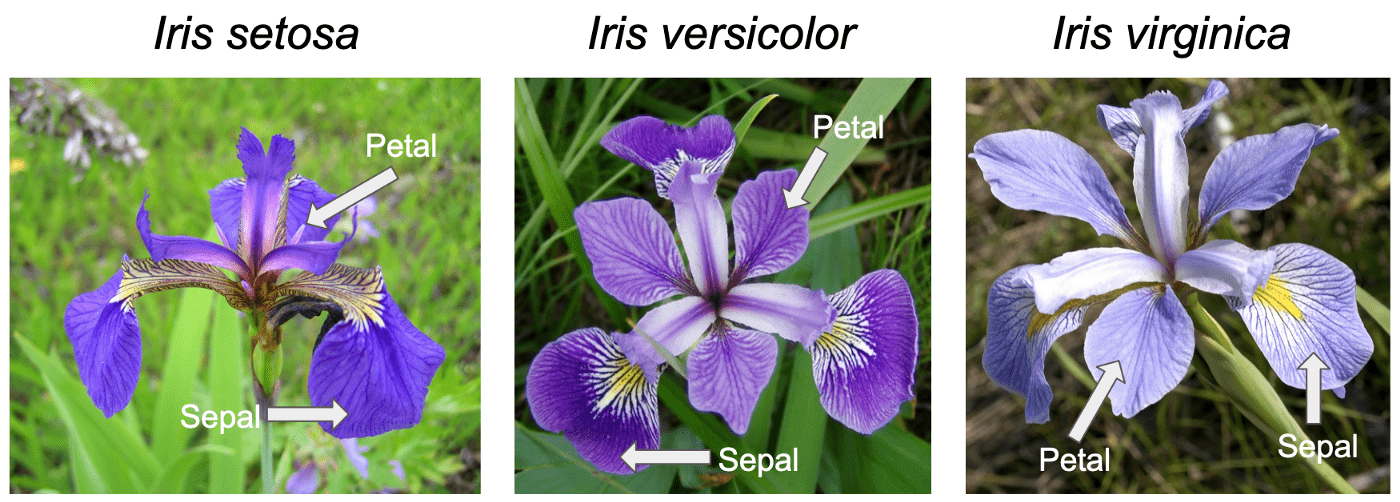

% Normalize the feature values to have zero mean and unit variance.
features = zscore(features);
features

features =     1.1700    1.2396    1.1765    1.1766    1.1362    1.1431    1.1233    1.1734    1.1932    1.2084    1.1699    1.1405    1.2180    1.1545    1.1689    1.0944    1.1486    1.1778    1.1921    1.1159    1.2175    1.1437    1.0780    1.2276    1.1254    1.2448    1.1882    1.1810    1.2017    1.1667    1.2012    1.2392    1.0583    1.0931    1.2084    1.2176    1.2197    1.2084    1.1745    1.1868    1.1655    1.3361    1.1290    1.1851    1.1109    1.2371    1.1058    1.1588    1.1568    1.1953
    0.4359    0.3068    0.4255    0.3922    0.4869    0.4707    0.5035    0.4148    0.3703    0.3384    0.4333    0.4463    0.3322    0.4645    0.4676    0.5675    0.4984    0.4315    0.3903    0.5177    0.3239    0.4834    0.5989    0.3257    0.4173    0.2685    0.3961    0.4088    0.3854    0.3974    0.3414    0.3297    0.5880    0.5618    0.3384    0.3746    0.3712    0.3384    0.4185    0.3956    0.4592    0.1113    0.4915    0.4205    0.4830    0.3188    0.5130    0.4378    0.45

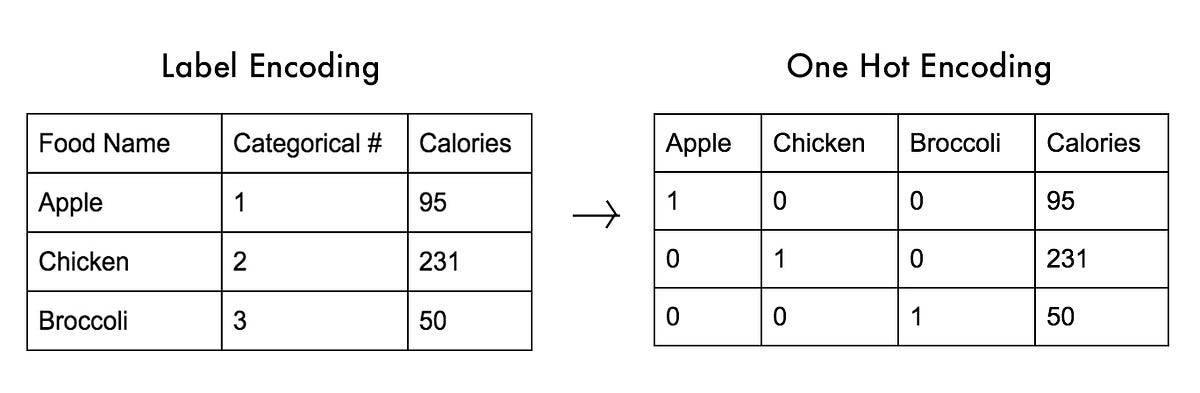

% Encode the target labels (species) into one-hot encoded vectors. 
% It's already in right one-hot encoded vector format.
labels

labels =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% Neural Network Architecture
hiddenLayerSize = 100; % Experiment with different values
net = patternnet(hiddenLayerSize);
net.trainFcn = 'trainlm'; % Experiment with different training functions
net.divideFcn = 'dividerand'; % Random division for training and testing
net = configure(net,features,labels);
view(net)

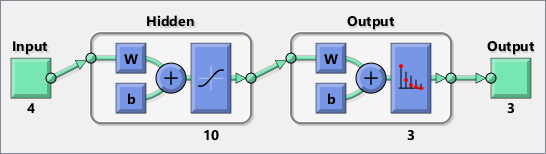

% Training
[net, tr] = train(net, features, labels);

% Evaluate on the test set
testFeatures = features(:, tr.testInd);
testLabels = labels(:, tr.testInd);
predictedLabels = net(testFeatures);

% Calculate accuracy

ans = 16

ans = 69

ans = 23

accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);
accuracy

accuracy = 0.6957

% Hyperparameter Tuning (Example: Number of hidden layers)
hiddenLayerSizes = [1,2,3,4,5,6,7,8,9, 10, 15]; % Experiment with different sizes

for i = 1:length(hiddenLayerSizes)
    hiddenLayerSize = hiddenLayerSizes(i);
    net = patternnet(hiddenLayerSize);
    net = configure(net,features,labels);
    testFeatures = features(:, tr.testInd);
    testLabels = labels(:, tr.testInd);
    predictedLabels = net(testFeatures);
    accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);
    disp(['Hidden Layer Size: ', num2str(hiddenLayerSize), ', Accuracy: ', num2str(accuracy)]);
end

Hidden Layer Size: 1, Accuracy: 0.3913
Hidden Layer Size: 2, Accuracy: 0.3913
Hidden Layer Size: 3, Accuracy: 0.34783
Hidden Layer Size: 4, Accuracy: 0.3913
Hidden Layer Size: 5, Accuracy: 0.34783
Hidden Layer Size: 6, Accuracy: 0
Hidden Layer Size: 7, Accuracy: 0.34783
Hidden Layer Size: 8, Accuracy: 0.26087
Hidden Layer Size: 9, Accuracy: 0.65217
Hidden Layer Size: 10, Accuracy: 0.086957
Hidden Layer Size: 15, Accuracy: 0.34783


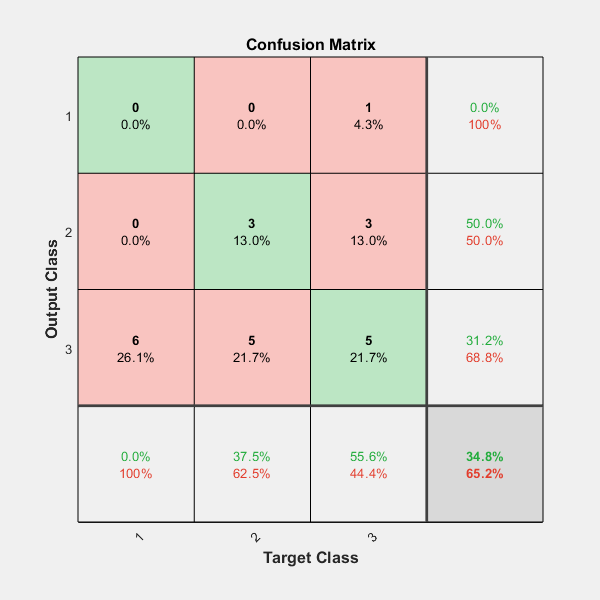

% Analysis and Visualization
figure;
plotconfusion(testLabels, predictedLabels);
title('Confusion Matrix');

% Conclusion
disp(['Final Accuracy: ', num2str(accuracy)]);

Final Accuracy: 0.91304


disp('Summary: ...'); % Provide your summary and reflection on the results

Summary: ...


% Hyperparameter Tuning
hiddenLayerSizes = 1:5;
trainingFunctions = {'trainlm', 'traingd', 'traingda', 'traingdm', 'traingdx'};
optimizationAlgorithms = {'sgd', 'adam', 'rmsprop', 'sgdm', 'sgdx'};

bestAccuracy = 0;
bestParams = struct();

for hiddenLayerSize = hiddenLayerSizes
    for trainFcn = trainingFunctions
        for optimAlgorithm = optimizationAlgorithms
            net = patternnet(hiddenLayerSize);
            net.trainFcn = trainFcn{1};
            net.divideFcn = 'dividerand'; % Random division for training and testing

            % Training
            [net, tr] = train(net, features, labels);

            % Evaluate on the test set
            testFeatures = features(:, tr.testInd);
            testLabels = labels(:, tr.testInd);
            predictedLabels = net(testFeatures);

            % Calculate accuracy
            accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);

            % Display results
            disp(['Hidden Layer Size: ', num2str(hiddenLayerSize), ...
                ', Train Function: ', trainFcn{1}, ...
                ', Optim Algorithm: ', optimAlgorithm{1}, ...
                ', Accuracy: ', num2str(accuracy)]);

            % Update best parameters if current model is better
            if accuracy > bestAccuracy
                bestAccuracy = accuracy;
                bestParams.hiddenLayerSize = hiddenLayerSize;
                bestParams.trainFcn = trainFcn{1};
                bestParams.optimAlgorithm = optimAlgorithm{1};
            end
        end
    end
end

Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 1


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.91304


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 1


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.86957


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.82609
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.52174
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.65217
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.6087
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.26087
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.65217
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.91304
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.91304
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.91304
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 1
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.91304
Hidden Layer Size: 1, Train Fu

Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.91304


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.91304


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.95652


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 1


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 1
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.52174
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.47826
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.78261
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.73913
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.86957
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 1
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: adam, Accuracy: 1
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.91304
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.95652
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.95652
Hidden Layer Size: 2, Train Function: tra

Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 1


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.95652


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 1


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.95652


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.52174
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.47826
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.91304
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.82609
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.43478
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.73913
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.91304
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.86957
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.86957
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 1
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.91304
Hidden Layer Size: 3, Train F

Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.95652


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 1


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.91304


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.91304


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.95652
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.69565
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.86957
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.95652
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.86957
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.82609
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 1
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.91304
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.86957
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 1
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.86957
Hidden Layer Size: 4, Train Functio

Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.95652


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 1


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 1


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.86957


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.91304
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.6087
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.86957
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.91304
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.86957
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.86957
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.95652
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.91304
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.95652
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.95652
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.95652
Hidden Layer Size: 5, Tr


disp(['Best Parameters - Hidden Layer Size: ', num2str(bestParams.hiddenLayerSize), ...
    ', Train Function: ', bestParams.trainFcn, ...
    ', Optim Algorithm: ', bestParams.optimAlgorithm, ...
    ', Best Accuracy: ', num2str(bestAccuracy)]);

Best Parameters - Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgd, Best Accuracy: 1


% Use the best parameters
bestHiddenLayerSize = bestParams.hiddenLayerSize;
bestTrainFcn = bestParams.trainFcn;
bestOptimAlgorithm = bestParams.optimAlgorithm;

% Create and train the final model
finalNet = patternnet(bestHiddenLayerSize);
finalNet.trainFcn = bestTrainFcn;
finalNet.divideFcn = 'dividerand'; % Random division for training and testing

% Training
[finalNet, tr] = train(finalNet, features, labels);


% Evaluate on the test set
testFeatures = features(:, tr.testInd);
testLabels = labels(:, tr.testInd);
predictedLabels = finalNet(testFeatures);

% Calculate accuracy
accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);

disp(['Final Model - Hidden Layer Size: ', num2str(bestHiddenLayerSize), ...
    ', Train Function: ', bestTrainFcn, ...
    ', Optim Algorithm: ', bestOptimAlgorithm, ...
    ', Accuracy: ', num2str(accuracy)]);

Final Model - Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 1
